This is a workbook to attempt to find a mixed effects model for the pilot data collected from Qualtrics for the EEE study. 

By Ben Graul

load('C:\Users\bgrau\GitHub\ieeg_affect\EEE\qualtrics\data\pilot_master_long.mat')


What do the data look like? We care about the rating that participants gave to an image after seeing a cue type. 

hicue_val = (master.img_rate(master.highcue_indx == 1));
locue_val = (master.img_rate(master.highcue_indx == -1));

highmean = mean(hicue_val)

highmean = 54.8393

lowmean = mean(locue_val)

lowmean = 50.6549

[h,p,ci,stats] = ttest(hicue_val, locue_val)

h = 1

p = 6.8903e-10

ci =     2.8578
    5.5111


stats = struct with fields:
    tstat: 6.1839
       df: 3935
       sd: 42.4524


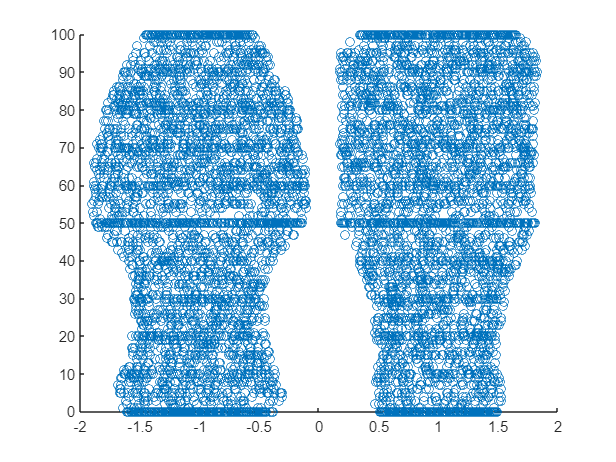


figure; hold on; 
swarmchart(master.highcue_indx, master.img_rate)

% Add mean line for comparison
%Clean up violin 

hold off;


cues = [hicue_val, locue_val];
% figure; 
% violinplot_canlab(cues, 'xlabel', {'High Cue', 'Low Cue'}, 'mc', 'k')

Let's start off with a very simple regression for predicting the valence score from the normative OASIS valence ratings.

We'll include a positive control for something that should have no relationship with the ratings for a sanity check.  

lme1 = fitlme(master, 'img_rate ~ Valence_mean')

lme1 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    img_rate ~ 1 + Valence_mean

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    69206    69227    -34600           69200   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE           tStat      DF      pValue        Lower      Upper  
    {'(Intercept)' }        -5.1575       0.58831    -8.7665    7870    2.2311e-18    -6.3107    -4.0042
    {'Valence_mean'}         1.0393     0.0097856     106.21    7870             0     1.0202     1.0585

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower     Upper 
    {'Res Std'}        19.617    

badlme = fitlme(master, 'img_rate ~ Half')

badlme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    img_rate ~ 1 + Half

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    76205    76226    -38099           76199   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat      DF      pValue     Lower      Upper 
    {'(Intercept)'}         51.932      1.0906      47.62    7870          0     49.794     54.07
    {'Half'       }        0.54345     0.68973    0.78791    7870    0.43077    -0.8086    1.8955

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower     Upper 
    {'Res Std'}        30.598      30.124    31.079


 It looks like there's a strong connection between these subject valence ratings and the OASIS valence ratings. This is not surprising. 

What if we add in the variable of interest? 

lme2 = fitlme(master, 'img_rate ~ Valence_mean + highcue_indx')

lme2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           3
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    img_rate ~ 1 + highcue_indx + Valence_mean

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    69118    69146    -34555           69110   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat      DF      pValue        Lower      Upper 
    {'(Intercept)' }        -5.1567     0.58497    -8.8154    7869      1.45e-18    -6.3034     -4.01
    {'highcue_indx'}         2.0889     0.21984     9.5018    7869    2.6831e-21      1.658    2.5199
    {'Valence_mean'}         1.0393     0.00973     106.82    7869             0     1.0203    1.0584

Random effects covariance parameters (95% CIs):

compare(lme1, lme2)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue
    lme1     3     69206    69227    -34600                               
    lme2     4     69118    69146    -34555    89.77     1          0     


This produces a significant improvement.  

Can we improve by adding subjects as a random effect? 

lme3 = fitlme(master, 'img_rate ~ Valence_mean + highcue_indx + (1|subj)')

lme3 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           3
    Random effects coefficients        123
    Covariance parameters                2

Formula:
    img_rate ~ 1 + highcue_indx + Valence_mean + (1 | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    68754    68789    -34372           68744   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE          tStat      DF      pValue        Lower      Upper  
    {'(Intercept)' }        -5.1567      0.73432    -7.0224    7869    2.3619e-12    -6.5962    -3.7173
    {'highcue_indx'}         2.0889      0.21182     9.8615    7869    8.2852e-23     1.6737     2.5041
    {'Valence_mean'}         1.0393     0.009375     110.86    7869             0     1.0209     1.0577

Random effects covariance 

compare(lme2, lme3, 'CheckNesting', true)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue
    lme2     4     69118    69146    -34555                               
    lme3     5     68754    68789    -34372    365.94    1          0     


This was also a significant improvement. 

What about if we cross the effect instead?

lme4 = fitlme(master, 'img_rate ~ Valence_mean * highcue_indx + (1|subj)')

lme4 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           4
    Random effects coefficients        123
    Covariance parameters                2

Formula:
    img_rate ~ 1 + highcue_indx*Valence_mean + (1 | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    68756    68798    -34372           68744   

Fixed effects coefficients (95% CIs):
    Name                                 Estimate     SE           tStat      DF      pValue       Lower        Upper   
    {'(Intercept)'              }          -5.1566      0.73432    -7.0223    7868    2.364e-12      -6.5961     -3.7172
    {'highcue_indx'             }           1.8302      0.56363     3.2472    7868    0.0011705      0.72533       2.935
    {'Valence_mean'             }           1.0393    0.0093749     110.86    7868        

compare(lme3, lme4, 'CheckNesting', true) %Not significant

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue 
    lme3     5     68754    68789    -34372                                 
    lme4     6     68756    68798    -34372    0.24535    1          0.62037


Doesn't seem to have any real benefit. Let's try to account for individual preference of a given image *within* each subject.

lme5 = fitlme(master, 'img_rate ~ Valence_mean + highcue_indx + (1 + Image|subj)')

lme5 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           3
    Random effects coefficients        246
    Covariance parameters                4

Formula:
    img_rate ~ 1 + highcue_indx + Valence_mean + (1 + Image | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    68748    68797    -34367           68734   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE           tStat      DF      pValue        Lower      Upper  
    {'(Intercept)' }        -5.6708       0.72099    -7.8653    7869    4.1704e-15    -7.0841    -4.2575
    {'highcue_indx'}         2.0892       0.21151     9.8777    7869    7.0647e-23     1.6746     2.5039
    {'Valence_mean'}         1.0393     0.0093612     111.02    7869             0      1.021     1.0577

Random effects

compare(lme3, lme5, 'CheckNesting', true) %sig 

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue   
    lme3     5     68754    68789    -34372                                  
    lme5     7     68748    68797    -34367    10.647    2          0.0048756


So currently, what we're seeing is that the normative valence rating provided with the OASIS set **and** the type of cue provided for a given image both impact the valence rating the participants give. 

Furthermore, a random effect ***crossing each image with each subject*** to estimate personal preference of a given image explains more of the data than just adding the subjects as a random effect. 

Can we see if the *category of cue type* or the *actual average observed in the cue* matter more?

lme6 = fitlme(master, 'img_rate ~ Valence_mean + cue_observed_mean + (1 + Image|subj)')

lme6 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           3
    Random effects coefficients        246
    Covariance parameters                4

Formula:
    img_rate ~ 1 + cue_observed_mean + Valence_mean + (1 + Image | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    68750    68799    -34368           68736   

Fixed effects coefficients (95% CIs):
    Name                         Estimate    SE          tStat      DF      pValue        Lower      Upper  
    {'(Intercept)'      }        -5.7314      0.72178    -7.9406    7869    2.2898e-15    -7.1463    -4.3165
    {'cue_observed_mean'}        0.14451     0.014824     9.7488    7869     2.497e-22    0.11545    0.17357
    {'Valence_mean'     }        0.90076      0.01702     52.922    7869             0     0.8674    0.93412

<

compare(lme5, lme6, 'CheckNesting', false) % p = 0?

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue
    lme5     7     68748    68797    -34367                                
    lme6     7     68750    68799    -34368    -2.4981    0          0     


This confused me, because the AIC and BIC are both higher for #6, but the p value is 0. I think this might mean that it can't compute the difference. Let's keep #5 moving forward. 

Another thing we should consider is that while each subject will see the same images, a given image is randomly assigned to be higher or lower than the normative mean. Does accounting for this improve our model?

lme7 = fitlme(master, 'img_rate ~ Valence_mean + highcue_indx + (1 + Image|subj) + (1 + highcue_indx|Image)')

lme7 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           3
    Random effects coefficients        374
    Covariance parameters                7

Formula:
    img_rate ~ 1 + highcue_indx + Valence_mean + (1 + Image | subj) + (1 + highcue_indx | Image)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    68231    68300    -34105           68211   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat      DF      pValue         Lower      Upper  
    {'(Intercept)' }        -5.335        1.928    -2.7671    7869      0.0056697    -9.1144    -1.5555
    {'highcue_indx'}        2.0927      0.20435     10.241    7869     1.8511e-24     1.6921     2.4933
    {'Valence_mean'}        1.0417      0.03105     33.549    7869    9.4374e-231    0.98082     1.102

compare(lme5, lme7, 'CheckNesting', true) % p = 0 again.

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue
    lme5      7    68748    68797    -34367                               
    lme7     10    68231    68300    -34105    523.09    3          0     


We had hypothesized that paired images would be rated similarly within subjects. Is this true?

lme8 = fitlme(master, 'img_rate ~ Valence_mean + cue_observed_mean + (1 + Pair|subj) +  (1 + highcue_indx|Image)')

lme8 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           3
    Random effects coefficients        374
    Covariance parameters                7

Formula:
    img_rate ~ 1 + cue_observed_mean + Valence_mean + (1 + Pair | subj) + (1 + highcue_indx | Image)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    68239    68309    -34110           68219   

Fixed effects coefficients (95% CIs):
    Name                         Estimate    SE          tStat      DF      pValue        Lower      Upper  
    {'(Intercept)'      }        -5.3075       1.9253    -2.7567    7869     0.0058518    -9.0816    -1.5334
    {'cue_observed_mean'}        0.14791     0.014724     10.046    7869    1.3333e-23    0.11905    0.17678
    {'Valence_mean'     }        0.89821     0.034134     26.314    7869    2.468e-


% lme8 = fitlme(master, 'img_rate ~ Valence_mean + highcue_indx + (1 + Image|subj) + (1 + highcue_indx|Pair)')
compare(lme8, lme7, 'CheckNesting', false) % p = 0; 5 is still best

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue
    lme8     10    68239    68309    -34110                               
    lme7     10    68231    68300    -34105    8.5078    0          0     


The `image pair x subj` interaction was not a significant improvement. That's a bit disappointing, and makes me wonder if the image pairs will actually be that helpful for comparisons. 


bestlme = lme5;

What does this look like right now?

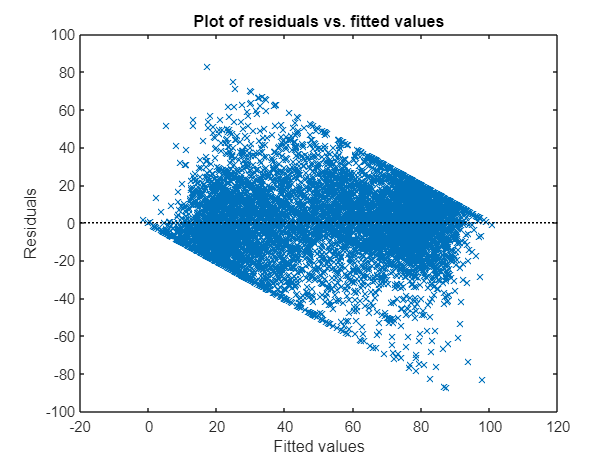

F = fitted(bestlme);
R = response(bestlme);
figure(); hold on;
plot(R,F,'rx')
xlabel('Response')
ylabel('Fitted')
hold off; 

figure();
plotResiduals(bestlme, 'fitted')

Current Questions:

What should the data look like when this is fitted correctly?